## Exercise 1

Consider the incoherent feed-forward depicted in the figure.

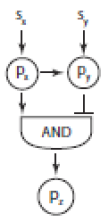

Assume that the signal sy is always present. We will also assume that the expression of px depends on sx such that production rate = max production rate * sx = βx * sx.

The Boolean rules for this system are:

- px -> IF sx > 0

- py -> IF px > Kxy

- pz -> IF px > Kxz AND NOT (py > Kyz)

**Parameters:**

- βx = maximal production rate of px

- βy = maximal production rate of py

- βz = maximal production rate of pz

- αx = rate of dilution/degradation of px

- αy = rate of dilution/degradation of py

- αz = rate of dilution/degradation of pz

Assume that you start with no px, py, or pz [px = py = pz = 0 mM].

## **TASK 1: Plot the levels of px, py, and pz over time.**

## **My attempt**

**Constants:**

% beta = beta_x = beta_y = beta_z = 1mM/h
beta = 1;
beta_zprime = 0.1;

%alpha = alpha_x = alpha_y = alpha_z = 1/h
alpha = 1;

% K measured in mM
Kxz = 0.4;
Kxy = 0.4;
Kyz = 0.5;

% t measured in h
t_on = 0;
t_off = 10;         %show in the range -1-20

#### 1. Plot the levels of px, py, and pz over time.

Defining the functions:

With:

- sx = 0 for -1 ≤ t < 0

- sx = 1 for 0 ≤ t < 10

% function Y = I1FFL_Ycurve(t, t_on,t_off,beta, alpha)
%     for i = 1:length(t)
%         if t(i) <= t_on
%             Y(i) = 0;
%         elseif t(i) > t_off
%             Y(i) = (beta/alpha)*exp(-alpha*t(i));
%         else
%             Y(i) = (beta/alpha)*(1-exp(-alpha*t(i)));
%         end
%     end
% end

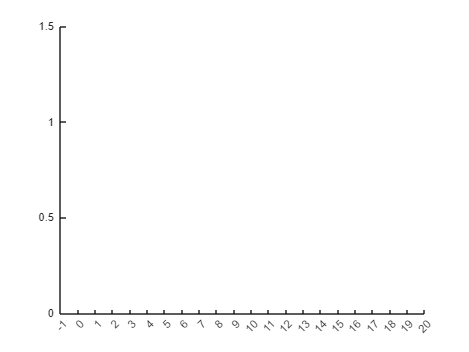

figure
t = linspace(t_on, 2*t_off, 100);
% plot(t, I1FFL_Ycurve(t, t_on,t_off,beta, alpha));
xlim([t_on-1 t_off+10]);
xticks(t_on-1:1:t_off+10)
ylim([0 (beta/alpha)+ 0.5])

## real solution:

**define all the different constants:**

the betas:

betax = 1;
betay = 1;
betaz = 1;             % the first value is betaz in the presence of X only, 
betaz_new = 0.1;        % the second value if the value for the presence of X anf Y.

the alphas:

alphax = 1;
alphay = 1;
alphaz =1;

the activation thresholds:

%the X concentration that is needed to activate Y: KXY
Kxy = 0.4;
%the X concentration that is needed to activate z: KXZ
Kxz = 0.4;
% the Y concentration to activate Z: Kyz
Kyz = 0.5;

computing the steady states

% is the ratio between max production constant beta and the degradation constant alpha:
Xst = betax/alphax;
Yst = betay/alphay;
Zst = betaz/alphaz;


define all the times:

t_on = 0;
t_off = 10;
t_plot = linspace(t_on,t_off,500);          %array with all the times between the ON and OFF steps

**FIrst plotting the curve of X **

%now consider the concentrations:
tx_activation = 0;
px_B = Xst*(1-exp(-alphax*t_plot));         %increasing part of the x curve:
figure
subplot(3,1,1)
% an horizontal line from -1 -> 0
txA = [-1, 0];
txY = [0, 0];
% the concentration curve from 0 -> 10
txB = t_plot;
yxb = px_B;
Xx = [txA, txB];
Yx = [txY, yxb];
plot(Xx, Yx);

**Then plotting all the curve of Y and Z**

However, based on whether the steady state concentration of X (Xst)  is enough or not to reach X accumulations sufficient for the various activation tresholds of Y and Z,

we have to consider these different scenarios:                                                                                           (use the numeric sliders to change the values of K and see the differences)

1. Both Y and Z inactive                                Xst < Kxy     AND     Xst <Kxz

2. Z active, Y inactive                                    Xst < Kxy     only         

3. Z never active, Y active                                                              Xst < Kxz     only

4. Z active, Y active                                       Xst > both tresholdsx

          4.1        Y unable to repress                Yst <  Kyz

          4.2        Z deactivated by Y (I1FFL)        

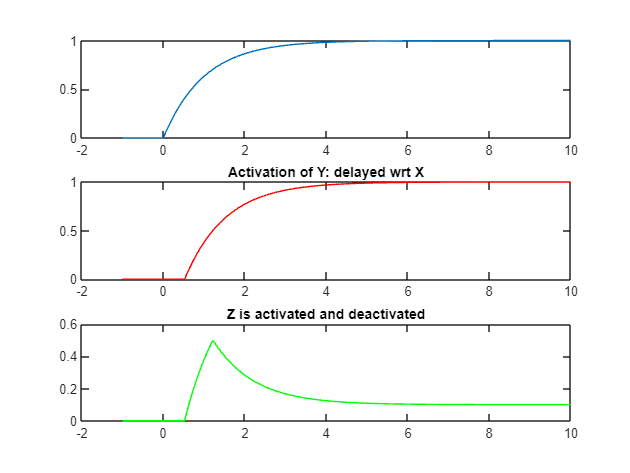

if (Xst < Kxy) && (Xst < Kxz)
    % SCENARIO 1                (the steady state is not enoguh to activate neither z or y, they are both at zero, always!)

    subplot(3,1,2)
    plot([-1, 10], [0,0], "red")
    title('Y always zero')
    subplot(3,1,3)
    plot([-1, 10], [0,0], "green")
    title('Z always zero')

else
    % this first inner condition account for the Y plotting under the various scenarios
    if (Xst < Kxy)
        % SCENARIO 2            (X is NOT able to activate Y! but is able to activate Z!!)

        subplot(3,1,2)
        plot([-1, 10], [0,0], "red")
        title('Y always zero')
    else
        % SCENARIO 3 & 4        (X is able to activate Y!)

        % what is the time that X needs to activate Y?
        timey_activation = -(1/alphax)*log((Xst-Kxy)/Xst);
        % now consider the concentration curve for Y
        py_B = Yst*(1-exp(-alphay*t_plot));
        % Y remains zero from -1 to the time of activation!
        % then it begins to increase exponentially
        subplot(3,1,2)
        XyA = [-1, timey_activation];
        yyA = [0,0];
        %after the activation time
        tyB = t_plot(t_plot > timey_activation);
        yyB = py_B(1:length(tyB));
        time_y = [XyA, tyB];
        Yy = [yyA, yyB];
        plot(time_y, Yy, "red");
        title('Activation of Y: delayed wrt X')
    end


    %this second inner condition account for the Z plotting under the different scenarios
    if (Xst < Kxz)
        % SCENARIO 3            (X is activated, Y is activated, Z remains zero)
        subplot(3,1,3)
        plot([-1, 10], [0,0], "green")
        title('we can not activate Z, not enough X')
    else
        % X can activate Z
        % compute the activation time: in which time X reaches the activation time of Z?
        tz_activation = -(1/alphax)*log((Xst-Kxz)/Xst);
        pz_B = Zst*(1-exp(-alphaz*t_plot));
        % at some point, the concentration of Z starts increasing
        if (Yst < Kyz) || (Xst < Kxy)
            % SCENARIO 4.1 & SCENARIO 2         (Y is activated but we can not decrease the Z cause never reaches the concentration 
                                                % or also we can never reached the concentration to activate Y Z is activated, but never repressed!)
            subplot(3,1,3)
            XzA = [-1, tz_activation];
            YzA = [0,0];
            XzB = t_plot(t_plot > tz_activation);
            YzB = pz_B(t_plot > tz_activation);
            Xz = [XzA, XzB];
            Yz = [YzA, YzB];
            plot(Xz, Yz, "green")
            title("Z increases and never decreases")
        else 
            % SCENARIO 4.2          (we have that Y is able to inactivate at a certain point)
            % T rep is the time from the activation of Y that is needed fro Y to
            Trep = (1/alphay)*log(1/(1-(Kyz/Yst)));
            Tz_inactivation = timey_activation + Trep;
            %to compute the decreasing part of the curve, we have to know the value at the begininng of the decreasing
            Z0 = Zst*(1-exp(-alphaz*(Tz_inactivation-tz_activation)));
            %compute now the decreasing value of Z, repressed:
            Zst_new = betaz_new / alphaz;
            pz_C = Zst_new + (Z0 - Zst_new)*exp(-alphaz*t_plot);
            subplot(3,1,3)
            XzA = [-1, tz_activation];
            YzA = [0,0];
            XzB = t_plot((t_plot>=tz_activation)&(t_plot<=Tz_inactivation));
            YzB = pz_B(1:length(XzB));
            XzC = t_plot(t_plot > Tz_inactivation);
            YzC = pz_C(1:length(XzC));
            Xz = [XzA, XzB, XzC];
            Yz = [YzA, YzB, YzC];
            plot(Xz, Yz, "green")
            title("Z is activated and deactivated")
        end
    end
end

noteworthy K scenarios seen:

SCENARIO 2:

Kxy > 1;        % (doesn't matter how much, nothing changed as i varied it)
0< Kxz < 1;     % (the closer to 0 the shorter is the Z delay, the closer is the 1 the later Z production start and very abruptly)
Kyz = 0.5;

SCENARIO 3:

0 < Kxy < 1;    % (the closer to 0 the shorter is the Y delay, the closer is the 1 the later Y production start and following a normal exponential curve)
Kxz < 1;        % (doesn't matter how much, nothing changed as i varied it)
Kyz = 0.5;

SCENARIO 4

% Z decreases first?????
Kxy =  0.3; Kxz = 0.7; Kyz = 0.5;

% apparently normal delayed Z curve
Kxy =  0.4; Kxz = 0.7; Kyz = 0.5;

% expected I1FFL behaviour
Kxy =  0.5; Kxz = 0.7; Kyz = 0.5;


% % always expected behaviour as long as Kxz < Kxy
Kxy =  0.7; Kxz = 0.1-6; Kyz = 0.5;         

## TASK 2:

Previously, we assumed that the signal sx was available for full activation. **Now**, let’s consider **sub-maximal signaling by sx**. 

Using the rate constants and activation thresholds in Exercise 2, plot the dynamics of pz for sx = [0.1:0.1:1]. 

What behavior do you see in the response of pz to different levels of sx? What function might this behavior serve in a living cell?

**define all the different constants:**

Sx = [0.1 : 0.1 : 1];

the betas:

betax = 1;
betay = 1;
betaz = 1;             % the first value is betaz in the presence of X only, 
betaz_new = 0.1;        % the second value if the value for the presence of X anf Y.

the alphas:

alphax = 1;
alphay = 1;
alphaz =1;

the activation thresholds:

%the X concentration that is needed to activate Y: KXY
Kxy = 0.4;
%the X concentration that is needed to activate z: KXZ
Kxz = 0.4;
% the Y concentration to activate Z: Kyz
Kyz = 0.5;

computing the steady states

% is the ratio between max production constant beta and the degradation constant alpha:
Yst = betay/alphay;
Zst = betaz/alphaz;

define all the times:

t_on = 0;
t_off = 10;
t_plot = linspace(t_on,t_off,500);          %array with all the times between the ON and OFF steps

**proceding with the task**

imagine the plot split in 3 parts:

A -> before Z starts production, while X is still accumulating

B -> from when Z starts production (tzA) to when it starts decreasing (Trep)

C -> after it Trep when Z production decreases

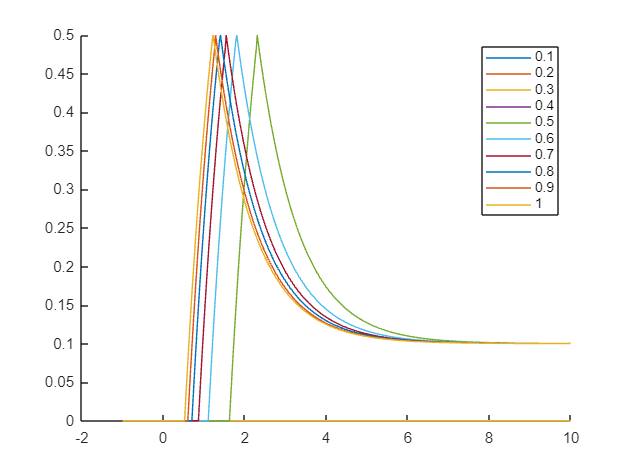

figure

hold on
for sx=0.1:0.1:1
    pXst = betax*sx/alphax;                                 % since I'm considering sub-maximal Sx concentrations I need to account it's ammount as well
    if pXst < Kxz
        plot([-1 10],[0 0],'DisplayName',num2str(sx));

    else
        tz_activation = -(1/alphax)*log((pXst-Kxz)/pXst);
        pz_B = Zst*(1-exp(-alphaz*t_plot));

        if(Yst < Kyz) || (pXst<Kxy)
            tzA = [-1 tz_activation];
            yzA = [0 0];
            tzB = t_plot(t_plot>=tz_activation);
            yzB = pz_B(1:length(tzB));
            
            tz = [tzA,tzB];
            yz = [yzA,yzB];
            plot(tz,yz,'DisplayName',num2str(sx))
        else
            Trep = (1/alphay)*log(1/(1-(Kyz/Yst)));
            tz_inactivation = tz_activation + Trep;
            z0 = Zst*(1-exp(-alphaz*Trep));
            pz_st_new = betaz_new/alphaz;
            pz_C = pz_st_new + (z0-pz_st_new)*exp(-alphaz*t_plot);
            tzA = [-1 tz_activation];
            yzA = [0 0];
            tzB = t_plot((t_plot>=tz_activation)&(t_plot<tz_inactivation));
            yzB = pz_B(1:length(tzB));
            tzC = t_plot(t_plot>=tz_inactivation);
            yzC = pz_C(1:length(tzC));
            tz = [tzA,tzB,tzC];
            yz = [yzA,yzB,yzC];
            plot(tz,yz,'DisplayName',num2str(sx))
        end
    end
end
legend('Location','northeast')

**Replying to the question:**

The less is the signal, the bigger is the initial delay before Y (and therefore also Z) start to accumulate.

Furthermore, only the Sx saturations > 40% are able to generate a pulse, since at lower ones I will never reach the treshold for Z production and I therefore have a flat 0 line

## TASK 3:

Increase Kxy to 0.8 and run your simulation again for sx = [0.1:0.1:1]. Now how does pz expression behave in response to various levels of sx?

**Replying to the question:**

if I increase the treshold for Y production, it means that I will still have possible production of Z starting from a 40% Sx signal saturation, but this production will never be stopped by the repressor Y, therefore leading to a complete production curve rather than a pulse.

Only when the Sx signal saturation reaches 80% I can finally overcome the Y treshold and start generating a pulse behaviour

## EXERCISE 2

1. Consider the SIM circuit in figure. 

The genes in this pathway are all regulated by the transcription factor X.

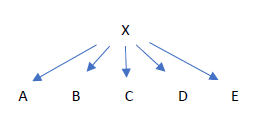

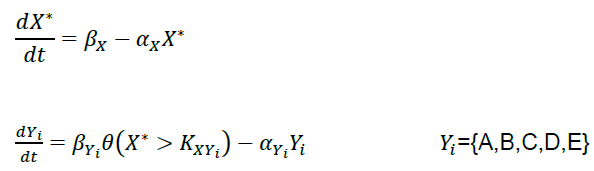

The activation signal SX arrives at t=0 and disappears at t=7 min. 

The gene E has the highest threshold parameter has 𝐾𝑋𝐸= Xss/2.

Find values for all 𝐾𝑋𝑌𝑖 such that 𝑌𝑖 will be induced at equal time intervals within [0, t([X=Xss/2]) (ss=steady state)

Parameters:

 𝛼𝑋,𝛼𝑌𝑖 =1/𝑚𝑖𝑛

 𝛽𝑋 , 𝛽𝑌𝑖 =1uM/𝑚𝑖𝑛

t_on = 0;
t_off = 7;   

#### task 1 

alphax = 1; alphay = 1; 
betax = 1; betay = 1;
Xss = betax/alphax;
Kxe = Xss/2;               %not a general rule for the SIM circuit, just in this case

teON = log(2)/alphax;      % since in this specific circuit we know tE happens at T1/2 because of its value of KXE       
taON = (1/5)*teON;
tbON = (2/5)*teON;
tcON = (3/5)*teON;
tdON = (4/5)*teON;

Kxa = Xss*(1-exp(-alphax*taON));        %since K parameters are defined on the base of the regulator protein not the produced one I use X equation
Kxb = Xss*(1-exp(-alphax*tbON));
Kxc = Xss*(1-exp(-alphax*tcON));
Kxd = Xss*(1-exp(-alphax*tdON));

#### task 2

Plot the activity of X* and its targets in the interval [0, 14] minutes.

What can you say about the timing of the decay of the various genes, as compared to the timing of induction?

Specifically describe the order and the duration of the decays.

Use 1/100 min as time step.

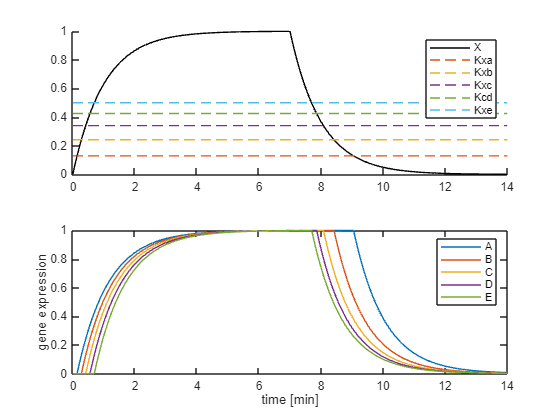

t = 0:0.01:14;
a = 1; b = 1;
X = Xss.*(1-exp(-a.*t));                                                % defining the first part of the X curve         use element-wise multiplication with time interval!
Xactivity = t(t<=7);                                                    % extracting the proper length of the first part instead of the whole one
X(length(Xactivity):end) = Xss*exp(-a.*(t(length(Xactivity):end)-7));   % appending the second part of the X curve
A = zeros(1,length(t));
B = zeros(1,length(t));
C = zeros(1,length(t));
D = zeros(1,length(t));
E = zeros(1,length(t));
txaDecay = 0; txbDecay = 0; txcDecay = 0; txdDecay = 0; txeDecay = 0;


for i=1:length(t)
    % computing and storing the times at which the decay start
    if txaDecay==0 && t(i)>=7 && X(i)<Kxa               %same condition as for the decay function + that the time was not initialized yet
        txaDecay = t(i);
    end
    if txbDecay==0 && t(i)>=7 && X(i)<Kxb
        txbDecay = t(i);
    end
    if txcDecay==0 && t(i)>=7 && X(i)<Kxc
        txcDecay = t(i);
    end
    if txdDecay==0 && t(i)>=7 && X(i)<Kxd
        txdDecay = t(i);
    end
    if txeDecay==0 && t(i)>=7 && X(i)<Kxe
        txeDecay = t(i);
    end


    % defining the production functions of each regulated gene
    if X(i) >= Kxa
        A(i) = (b/a).*(1-exp(-a.*(t(i)-taON)));
    end
    if X(i) >= Kxb
        B(i) = (b/a).*(1-exp(-a.*(t(i)-tbON)));
    end
    if X(i) >= Kxc
        C(i) = (b/a).*(1-exp(-a.*(t(i)-tcON)));
    end
    if X(i) >= Kxd
        D(i) = (b/a).*(1-exp(-a.*(t(i)-tdON)));
    end
    if X(i) >= Kxe
        E(i) = (b/a).*(1-exp(-a.*(t(i)-teON)));
    end


    % defining the decaying functions of each regulated gene
    if t(i)>=7 && X(i)<Kxa                              % to have both conditions True I need the AND operator, so I also need to accomodate my second condition to the way my first condition works = false, TRUE (TxaDecay)
        A(i) = exp(-a.*(t(i)-txaDecay));                % X(t) for the second condition = true, false, false, TRUE      (taON, TxaDecay, t(i))    
    end
    if t(i)>=7 && X(i)<Kxb
        B(i) = exp(-a.*(t(i)-txbDecay));
    end
    if t(i)>=7 && X(i)<Kxc
        C(i) = exp(-a.*(t(i)-txcDecay));
    end
    if t(i)>=7 && X(i)<Kxd
        D(i) = exp(-a.*(t(i)-txdDecay));
    end
    if t(i)>=7 && X(i)<Kxe
        E(i) = exp(-a.*(t(i)-txeDecay));
    end
end
figure
subplot(2,1,1)
hold on
plot(t,X,'k')
plot(t,Kxa * ones(size(t)), '--')
plot(t,Kxb * ones(size(t)), '--')
plot(t,Kxc * ones(size(t)), '--')
plot(t,Kxd * ones(size(t)), '--')

plot(t,Kxe * ones(size(t)), '--')

txeDecay = 7.7000

txdDecay = 7.8600

txcDecay = 8.0800

txbDecay = 8.4200

txaDecay = 9.0500

legend('X','Kxa','Kxb','Kxc','Kcd','Kxe')

ans = 5.0494

hold off

ans = 3.1018

subplot(2,1,2)

ans = 2.5969

plot(t,A,t,B,t,C,t,D,t,E)

ans = 2.5608

xlabel('time [min]')

ans = 2.9575

ylabel('gene expression')
legend('A','B','C','D','E')
txeDecay,txdDecay,txcDecay,txbDecay,txaDecay      % not uniform separation of times in the decay + LIFO order
(txeDecay -7 )/taON         % first out 5.1 times faster than first in
(txdDecay -7 )/tbON         % second out 3.1 times faster than second in
(txcDecay -7 )/tcON         % third one 2.6 times faster starting its own decay rather than its production
(txbDecay -7 )/tdON
(txaDecay -7 )/teON

unfortunately I didn't manage to make the color match, but look at the legend to match them properly